# W7 DC Motor

### DC Motor Experiment: 

At two voltages *V1* and *V2*, the resulting torque is measured at two different speeds as follows:

*T1 = a · V1 − b · ω1*

*T2 = a · V2 − b · ω2*

Re-write the relationship below in matrix form by filling in the elements of 2×2 matrix *A*.

load data.mat % load motor data table

% initialize variables 
V1 = motor.voltage(1);
V2 = motor.voltage(2);
omega_1 = motor.omega(1);
omega_2 = motor.omega(2);
T1 = motor.torque(1);
T2 = motor.torque(2);

A = [V1 -omega_1; V2 -omega_2] % matrix A

A =     12    -1
    15    -2


T = [T1; T2] % torque matrix

T =    28.3388
   27.8585


### Matrix Inverse: 

In MATLAB, compute the coefficients *a* and *b* using the function inv(A):

coeff = inv(A) * T; % calculate a and b coefficients
a = coeff(1)

a = 3.2021

b = coeff(2)

b = 10.0867

### Plotting: 

Produce the torque-speed graphs corresponding to voltages *V1* and *V2*, respectively, in a single figure. Attach title, labels, and legend. (For an example graph, refer to Lecture Notes #1.)

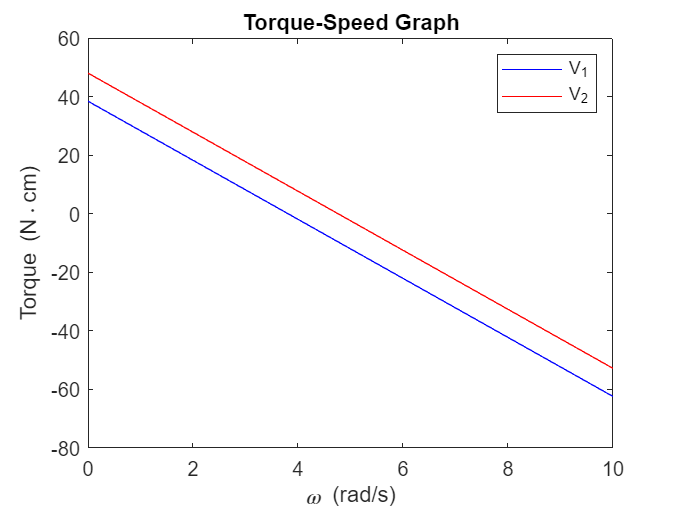

% plot torque-speed graph for V1
x = 0:10;
y1 = a*V1 - b*x; 
plot(x,y1,'b')
hold on

% plot torque-speed graph for V2
y2 = a*V2 - b*x;
plot(x,y2,'r')

title('Torque-Speed Graph')
legend('V_1','V_2')
xlabel('\omega (rad/s)')
ylabel('Torque (N\cdotcm)')

### Validation: 

Confirm that the characteristic curve above corresponds to the PMI Motors small permanent

magnet DC motor with the following physical properties.

Torque constant: *kt* = 3.01 N cm/A

Back emf constant: *kv* = 3.15 V/krpm

Armature resistance: *R* = 0.940 Ωz

% initialize variables
kt = 3.01;
kv = 3.15;
R = 0.940;

% calculate true values for a and b coefficients 
true_a = kt/R

true_a = 3.2021

true_b = (kt * kv)/R

true_b = 10.0867